# 動画のラベリング(アノテーション)

目標座標(x, y)をビデオラベラーを使ってアノテーション

このスクリプトの実行方法がわからない方は, [こちらの説明](matlab:open('how_to_use_livescript_jp.mlx'))をお読みください.

## 初期化

clear; close all; clc; rng('default');
show_message("annotateVideo_jp",1);

## ラベリング用の動画生成

% 動画一覧を取得
videoDS = fileDatastore('.','FileExtensions','.avi','ReadFcn',@(file)vision.VideoFileReader(file));

% 動画ファイルごとに処理
for k = 1:numel(videoDS.Files)
    [dirname,filename,ext] = fileparts(videoDS.Files{k});

    writeFilename = fullfile(dirname,[filename,'_for_labeler.mp4']);
    if ~exist(writeFilename,'file')
        % 動画書き込みオブジェクトの設定
        videoWriter = vision.VideoFileWriter(writeFilename,...
            'FileFormat','MPEG4','Quality',90);

        % 動画読み込みオブジェクト
        videoReader = vision.VideoFileReader(videoDS.Files{k});
        videoReader.VideoOutputDataType = 'uint8';

        % 動画を逐次読み込んで最初のラベリング点を描画
        while ~videoReader.isDone
            I = videoReader();
            % 目印となる円を描画
            I = insertShape(I,"FilledCircle",[size(I,2)/2, size(I,1)-10,5],"Color","red");
            % コメントを描画
            I = insertText(I,[size(I,2)/2+5, size(I,1)-10],"←最初にここをクリック",...
                "AnchorPoint","leftCenter","Font","MS PGothic","TextColor","red");
            % 動画を書き出し
            videoWriter(I);
        end

        % 動画をファイナライズ
        release(videoWriter);
    end
end
show_message("annotateVideo_jp",2);

## ビデオラベラーを開く

videoLabeler

MATLABの「アプリ」タブから「ビデオラベラー」をクリックして開いてもOK

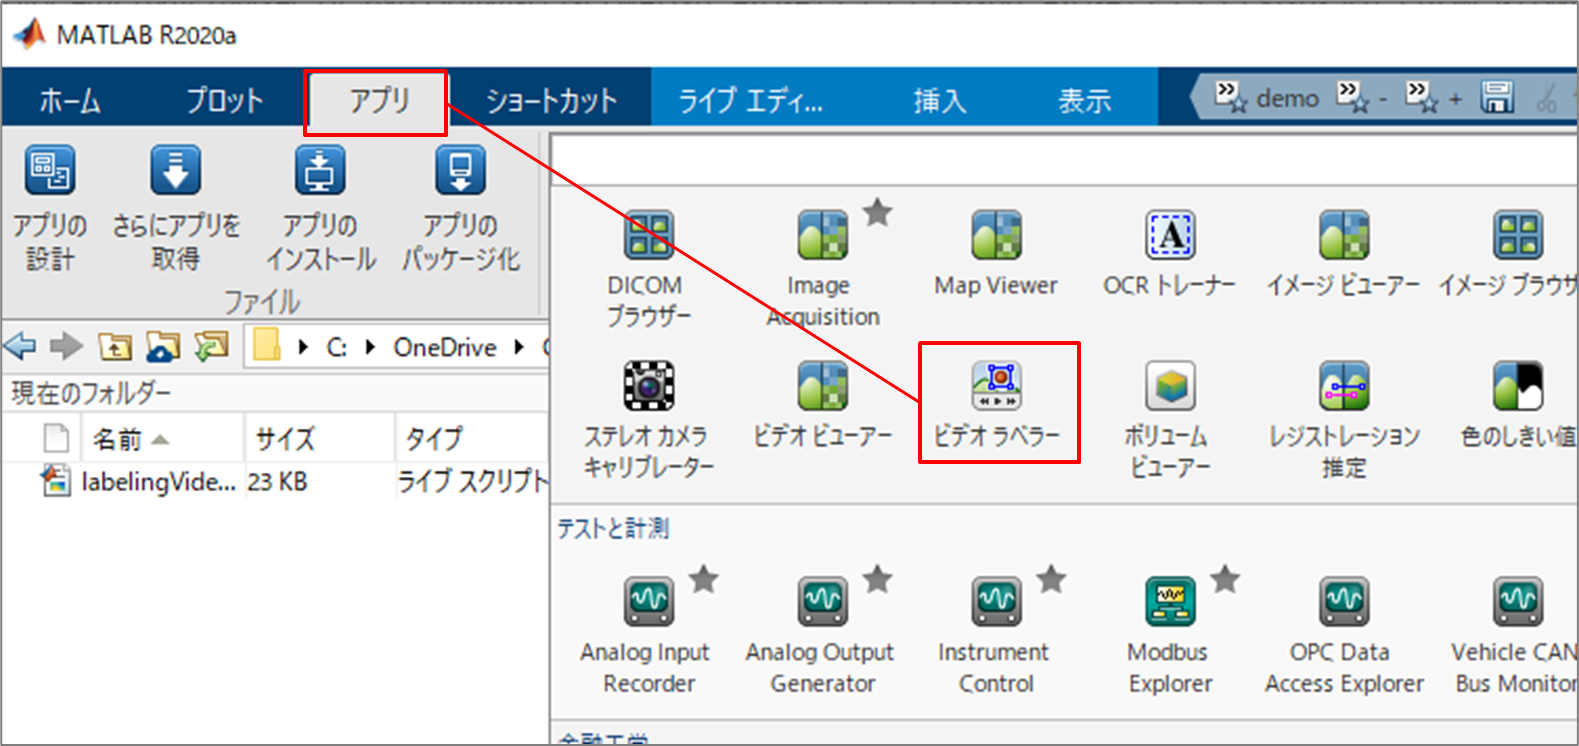

## 動画の読み込み

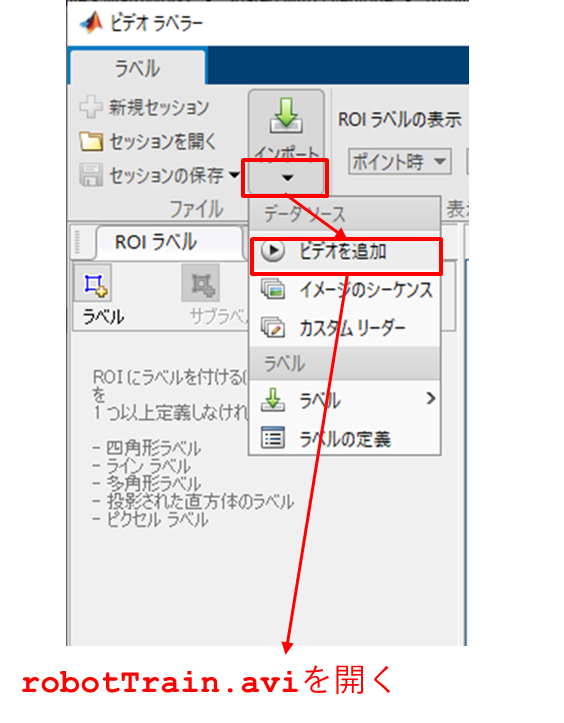

## ラベルを定義する

ラベルを追加し、「ラベル名」を「WhiteLine」、種類を「Line」にする。

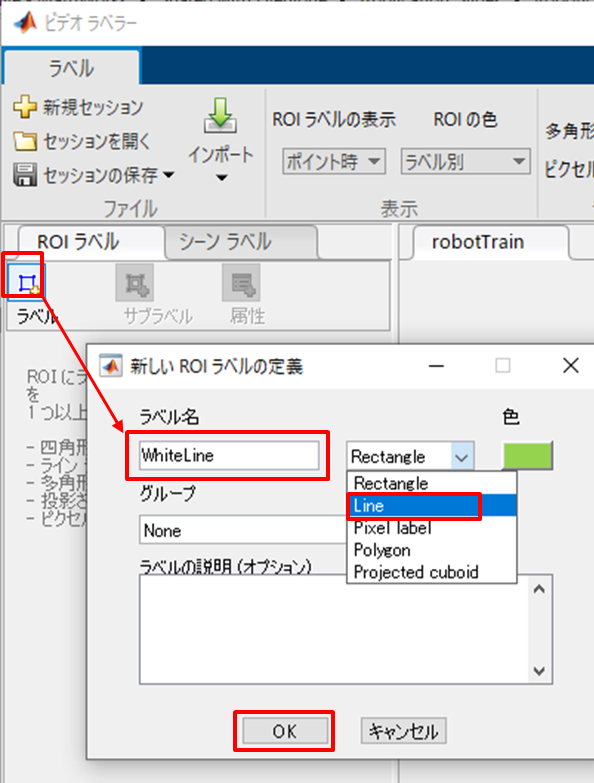

## 画像下から上に向かって目標座標をラベリング

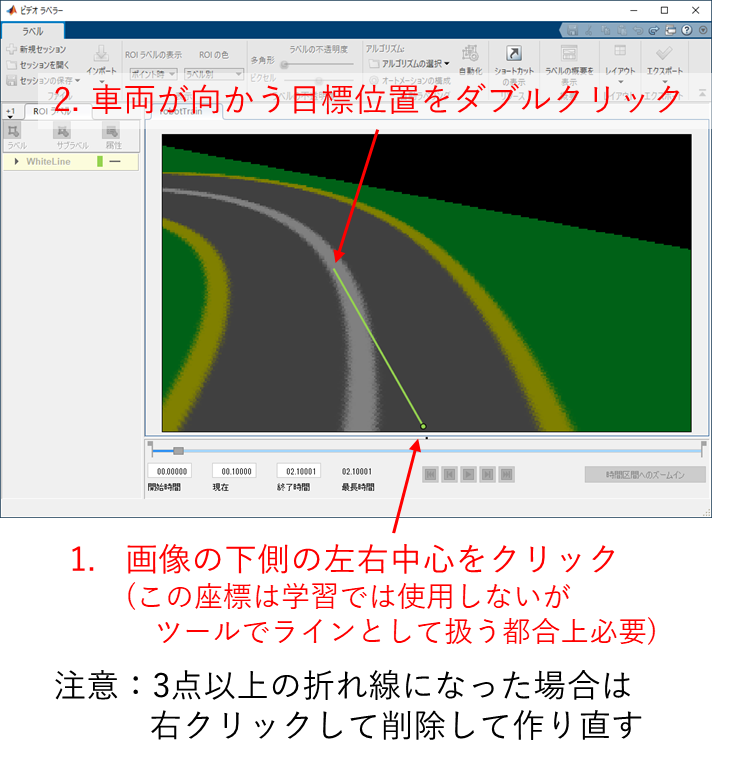

## 適宜ラベリング結果をセッションとして保存する

　(ファイル名はデフォルトで構わない)

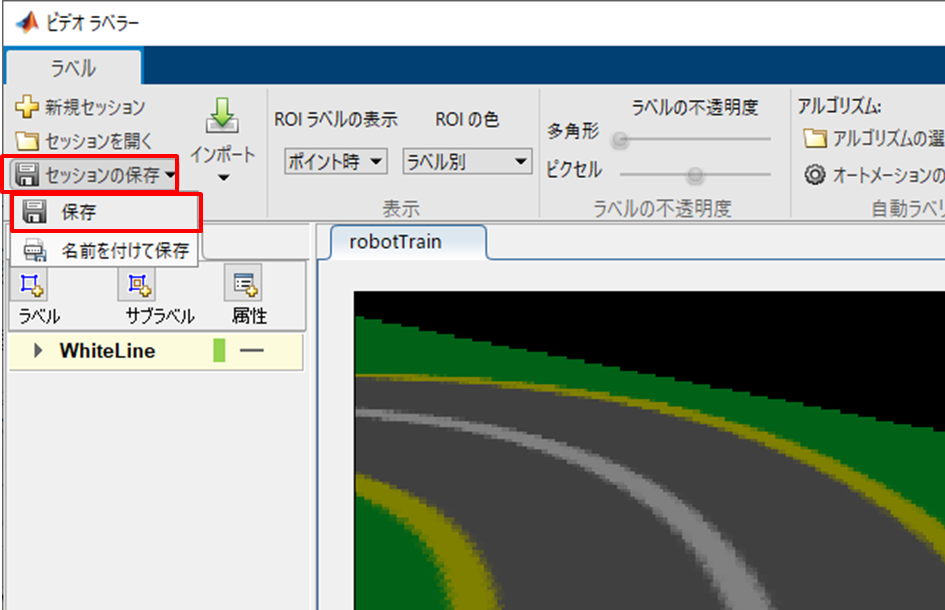

## ラベルを保存

「`exportedLabels.mat`」として保存する

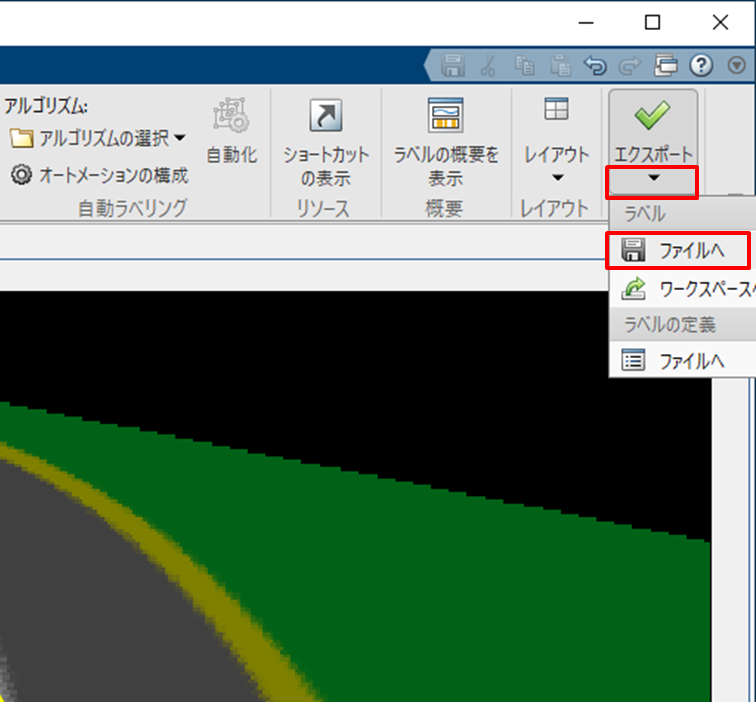

## 次のステップ

[trainWhiteLine_jp.mlx](matlab:open('trainWhiteLine_jp.mlx')) で回帰ネットワークを学習する

## [メニューに戻る](matlab:open('workshopMenu_jp.mlx'))

*Copyright 2021 The MathWorks, Inc.*